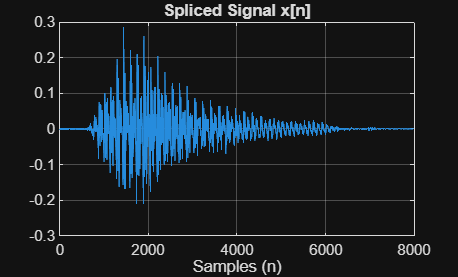

% Part A
[y, Fs] = audioread('sad.wav');
N = length(y);
t = (0:N-1) / Fs;

t_start = 0.6011787;
t_end = 1.1004;

idx_start = round(t_start * Fs); 
idx_end   = round(t_end * Fs);

if idx_start < 1
    idx_start = 1;
end

spliced = y(idx_start : idx_end);

% Plot the spliced signal
figure;
plot(spliced);
title('Spliced Signal x[n]');
xlabel('Samples (n)');
grid on;

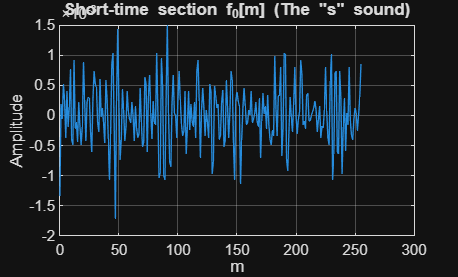

% Part B
% a)

M = 256;
m = 0:M-1;

f0 = spliced(1:M);

% Plot
figure;
plot(m, f0);
title('Short-time section f_{0}[m] (The "s" sound)');
xlabel('m'); ylabel('Amplitude');
grid on;

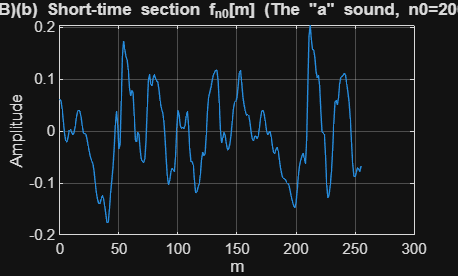

% Part B
% b)
n0 = 2000;
f_n0 = spliced(n0+1 : n0+M);

figure;
plot(m, f_n0);
title(['(B)(b) Short-time section f_{n0}[m] (The "a" sound, n0=', num2str(n0), ')']);
xlabel('m'); ylabel('Amplitude');
grid on;

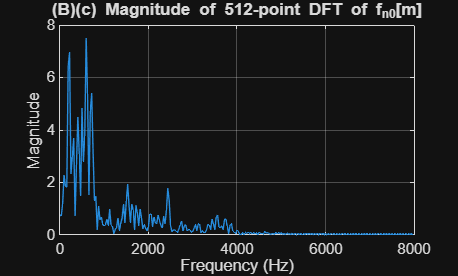

% Part B
% c)

N_fft = 512;
X_k = fft(f_n0, N_fft);

k = 0:N_fft-1;
freq_axis = k * (Fs / N_fft);

half_N = N_fft/2;

figure;
plot(freq_axis(1:half_N), abs(X_k(1:half_N)));
title('(B)(c) Magnitude of 512-point DFT of f_{n0}[m]');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
grid on;